# Problem 1

Part a

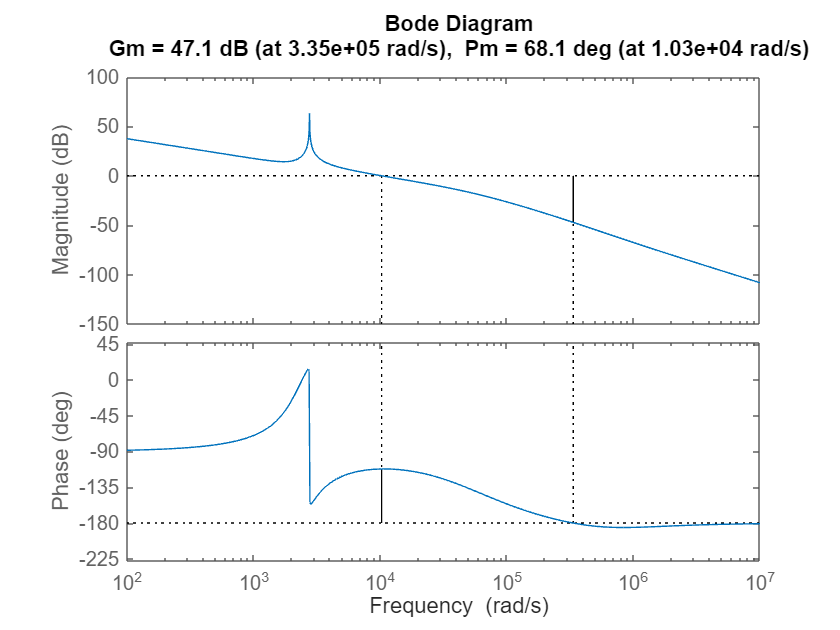

s = tf('s');
G = 20 * (2*pi*440)^2 / (s^2 + 2*0.0009*2*pi*440*s + (2*pi*440)^2) * [1 0.006 ; 0.006 1];
[K, CL, GAM] = loopsyn(G(1,1), 10000/s);
margin(G(1,1)*K)

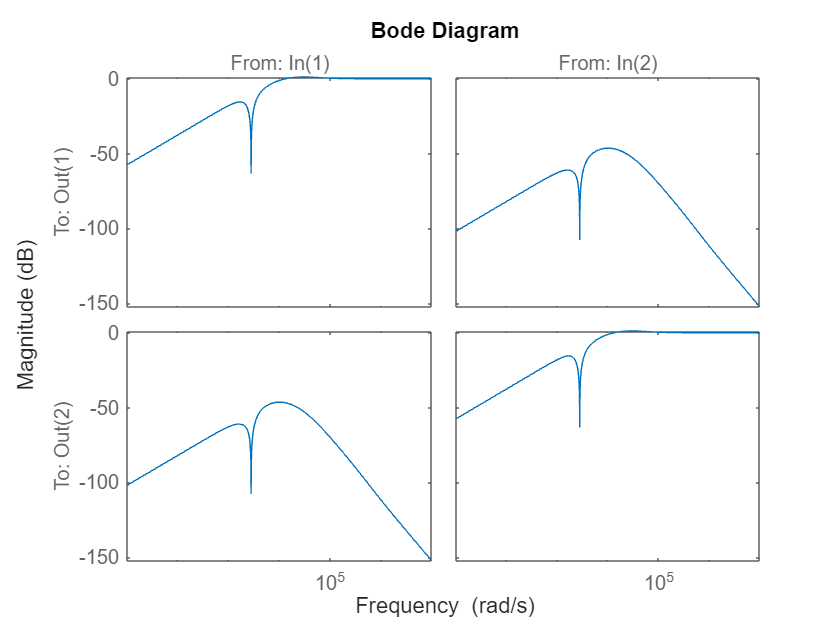

C = [K 0 ; 0 K];
diag = inv(eye(2)+G*C);
bodemag(diag)

Part b

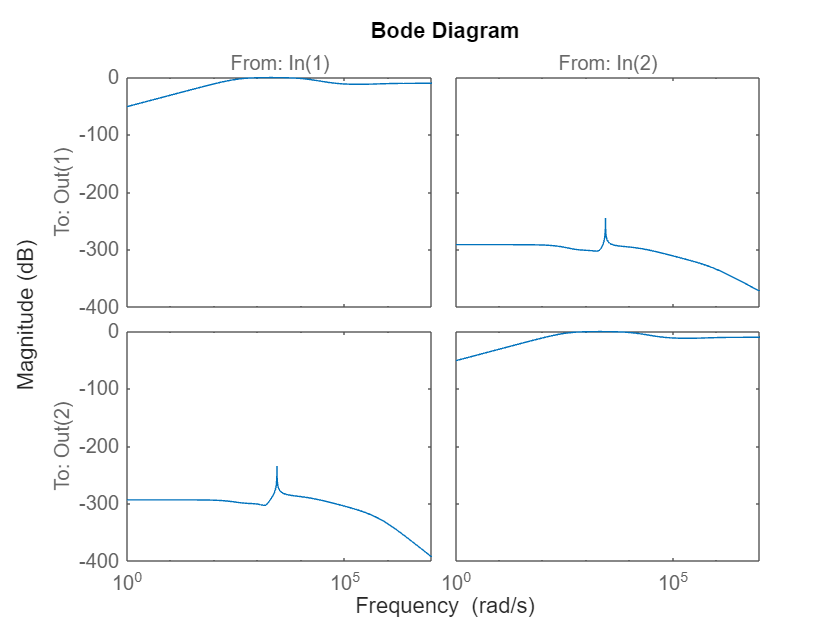

W = inv(G);
C = W*[K 0 ; 0 K];
dd = inv(eye(2)+G*C);
bodemag(dd)

Part c

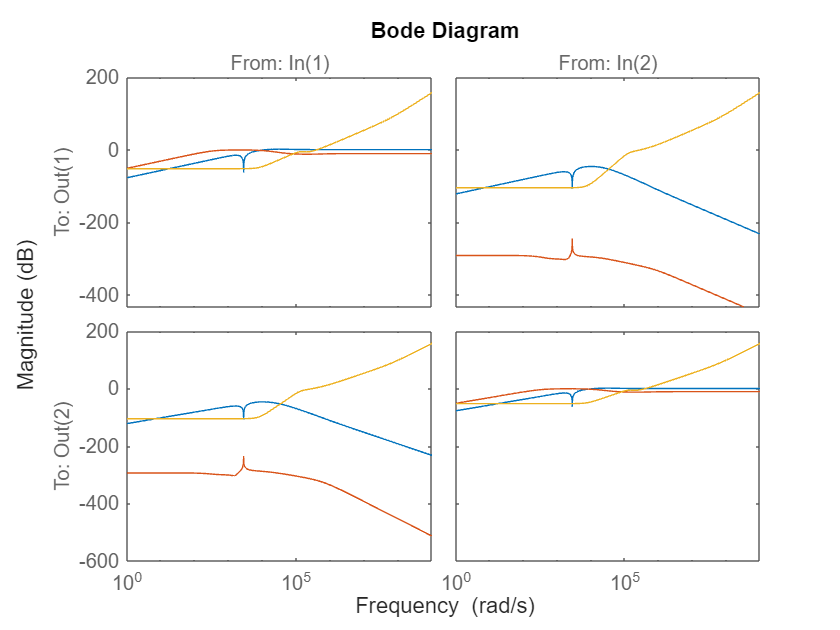

Ws = makeweight(2, 10000, 1/1000, 0, 2);
[K, CL, GAM] = mixsyn(G, [Ws 0 ; 0 Ws], [], []);
mix = inv(1+G*K);
bodemag(diag, dd, mix)

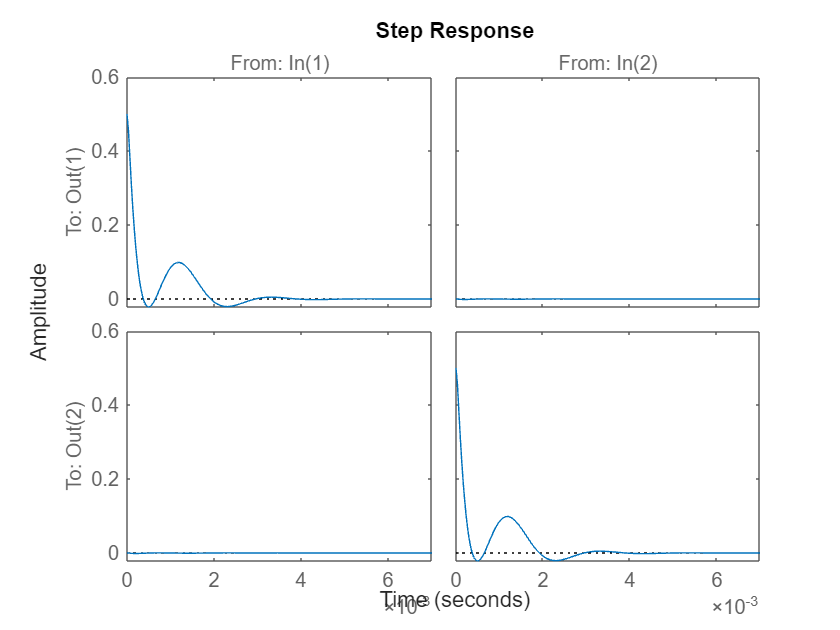

step(feedback(diag, eye(2)))

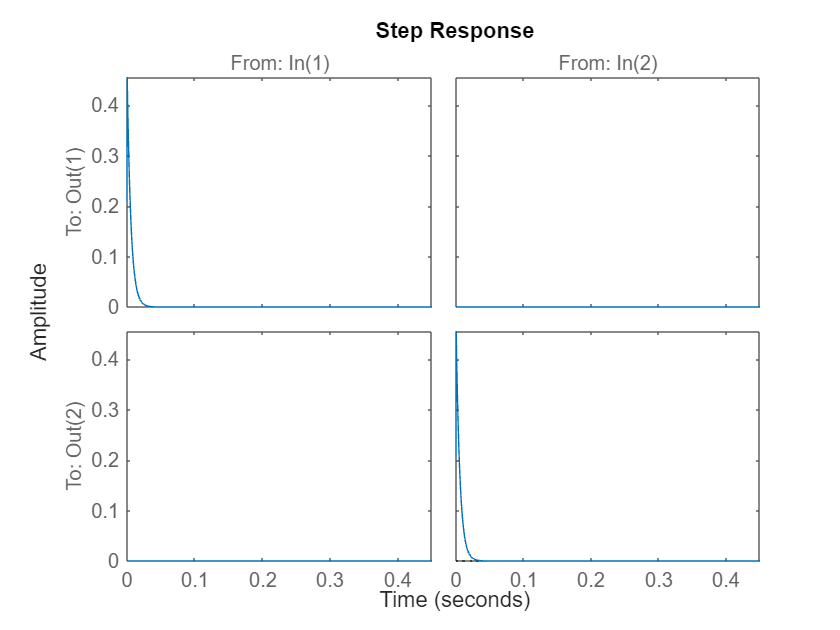

step(feedback(dd, eye(2)))

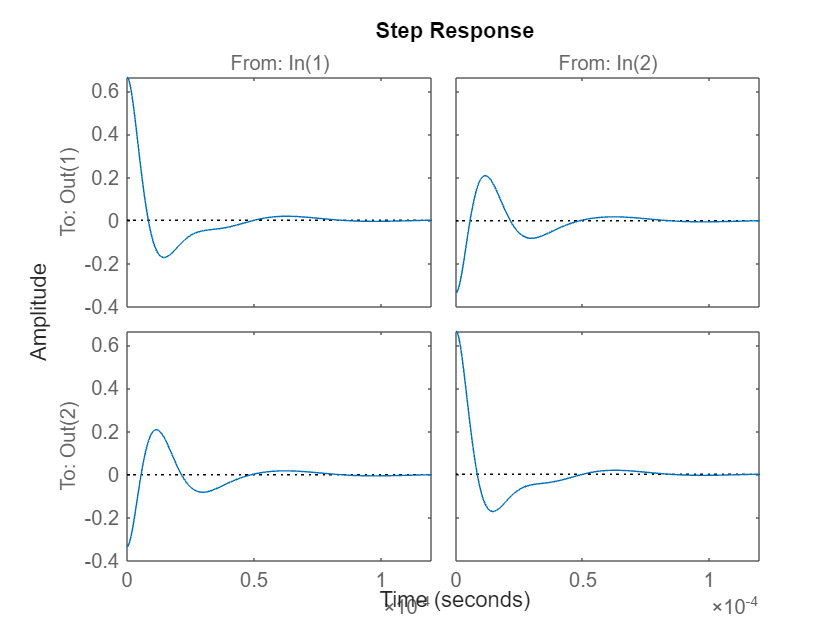

step(feedback(mix, eye(2)))

# Problem 2

Part c

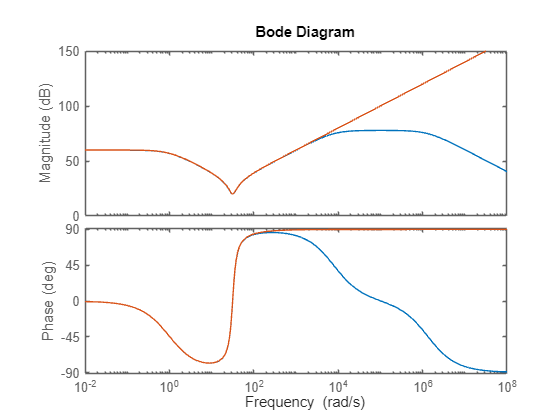

s = tf('s');
G = (s+1) / (s^2 + 10*s + 1000);
Wu = 1/100;
Wm = (s+10000) / (0.01*s+1);
P = [0 Wu ; Wm -Wm*G ; 1 0];
[K, CL, GAM] = hinfsyn(P, 1, 1);
bode(K, inv(G))

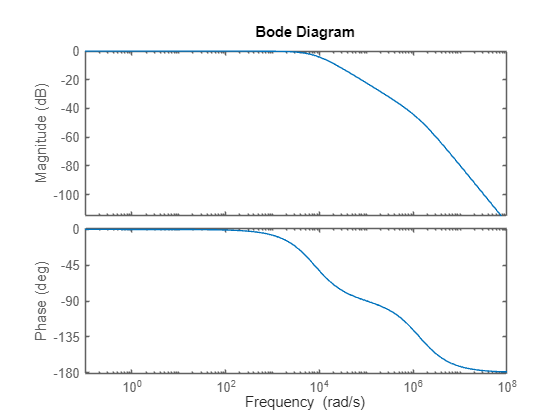

bode(G*K)